# Apuntes de Clase - Teorema del Límite Central y Función Cuantil

Herramientas Matemáticas para el Manejo de la Información

Sesión 13 - 11 de mayo de 2024

# Teorema del Límite Central

Si $\bar X$ es la media aritmética de una muestra aleatoria, de tamaño $n$, tomada de una población con media $\mu_X$ y varianza finita $\sigma_X^2$, entonces la forma límite de la distribución de:


$$Z =\frac{\bar{X}-\mu_X}{\frac{\sigma_X}{\sqrt{n}}}$$


cuando $n\rightarrow \infty$, es la distribución normal estandar $\mathcal{N}(0,1)$. Esto es:


$$Z\leadsto \mathcal{N}(0,1)$$


y se lee: "la variable aleatoria Z converge en distribución a una normal estandar". O bien, el símbolo $\leadsto$ se puede interpretar como "se distribuye como (cuando n tiende a infinito)".

## Ejemplos con Distribuciones Continuas

Datos Normalmente Distribuidos:


$$X_i \sim \mathcal{N}\left( \mu,\sigma \right)$$
     

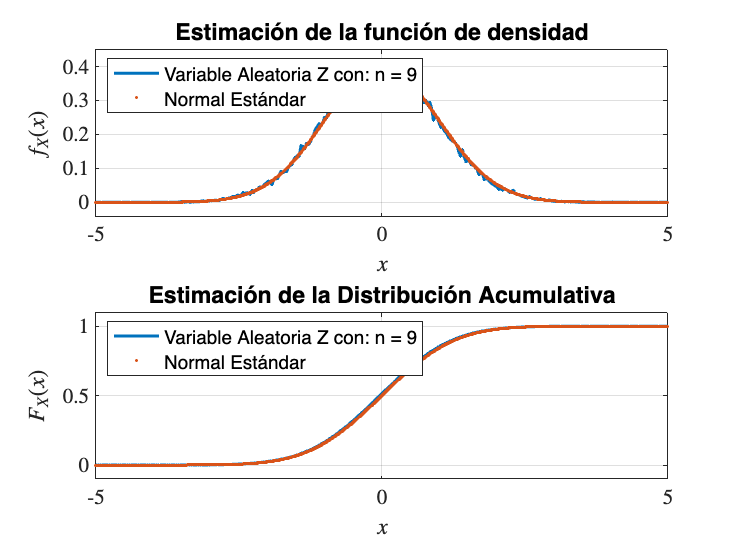

mu = 2;         % Media de la población
sigma = 5;    % Desviación estándar de la población
n = 9; % Tamaño de la Muestra, n>1
figure(1);
limitecentralnormal(mu,sigma,n); % Comparación de Z y Normal estándar

Datos Uniformemente Distribuidos:


$$X_i \sim \mathcal{U}\left(a,b\right)$$
     

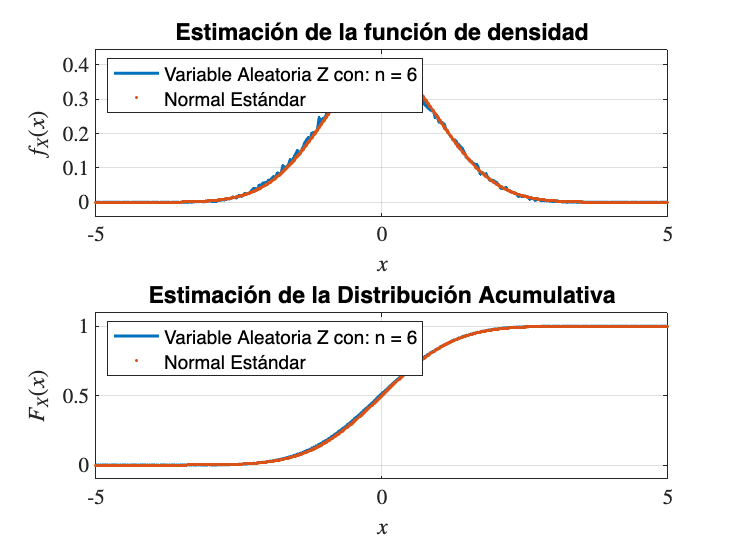

a = -2;    % Valor mínimo
b = -1;    % Valor máximo
n = 6; % Tamaño de la Muestra, n>1
figure(2);
limitecentraluniforme(a,b,n); % Comparación de Z y Normal estándar

Datos Exponencialmente Distribuidos:


$$X_i \sim \text{Exp}\left(\lambda\right)$$


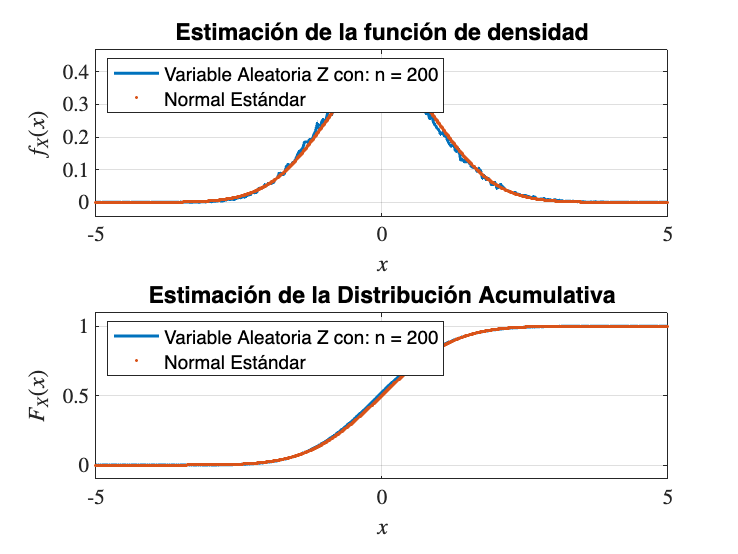

lambda = 24;   % Parámetro de la distribución exponencial
n = 200; % Tamaño de la Muestra, n>1
figure(3);
limitecentralexponencial(lambda,n); % Comparación de Z y Normal estándar

## Ejemplos con Distribuciones Discretas

Experimento del lanzamiento de una moneda


$$\begin{array}{cc}
X & P[X=x] \\
0 & 0.5 \\
1 & 0.5
\end{array}$$


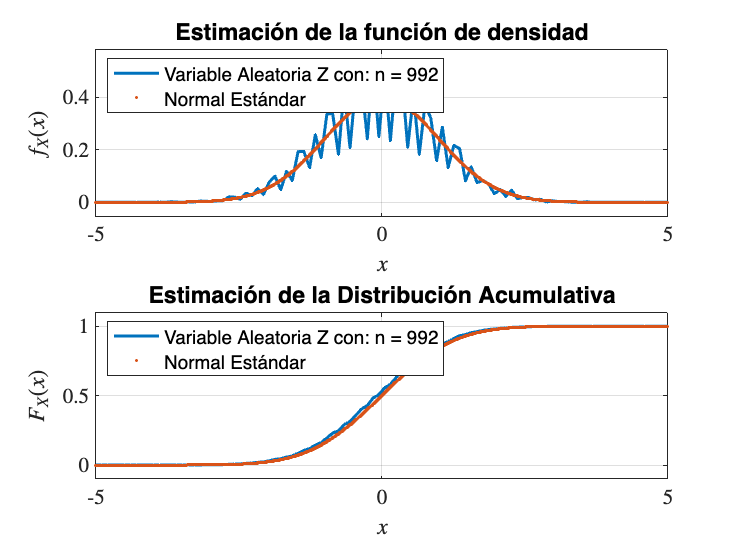

x = [0,1];       % Valores que toma la variable aleatoria discreta
p = [0.5,0.5];   % Probabilidades asociadas
n = 992; % Tamaño de la Muestra, n>1
figure(4);
limitecentraldiscreta(x,p,n); % Comparación de Z y Normal estándar

## Ejercicio en clase

¿Cuántos resultados diferentes tiene el experimento aleatorio: "promedio del lanzamiento de tres monedas"? En cada lanzamiento el resultado es 0 o 1.

## Estudiantes que resolvieron el ejercicio

Brayan Oviedo

Jeisson Andrés Hernández

Vivian Sánchez

Experimento del Partido de Fútbol (Torneo nuevo: Final de la Champions)


$$\begin{array}{cc}
X & P[X=x] \\
1 & 0.8 \\
2 & 0.1 \\
3 & 0.1
\end{array}$$


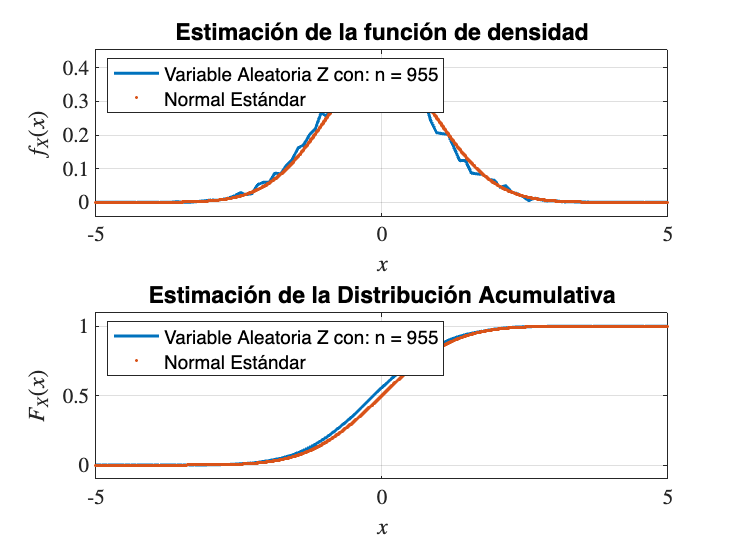

x = [1,2,3];            % Valores que toma la variable aleatoria discreta
p = [0.8,0.1,0.1];      % Probabilidades asociadas
n = 955; % Tamaño de la Muestra, n>1
figure(5);
limitecentraldiscreta(x,p,n); % Comparación de Z y Normal estándar

## Ejercicio en clase

¿Cuántos resultados diferentes tiene el experimento aleatorio del promedio de la variable aleatoria: "resultado de la final de la *Champions League*"?.

## Estudiante que resolvió el ejercicio

Karen Núñez

## Verificación del Teorema del Límite Central usando los datos del acelerómetro

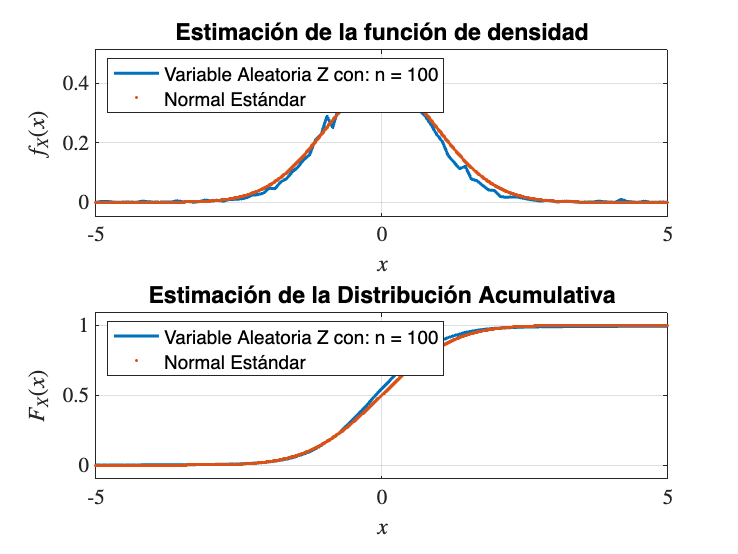

n = 100; % Tamaño de la Muestra, n>1
figure(6);
limitecentralacel(n);

## Observaciones

- El teorema del límite central se puede aplicar para poblaciones continuas o discretas y para cualquier tipo de distribución (con media $\mu_X$ y varianza finita $\sigma_X^2$). Tanta generalidad es extrañada en el estudio de los estimadores, porque, con excepción del estimador de la media, los demás estimadores suelen tener como restricción el tipo de distribución de la población (por ejemplo, que los resultados son válidos si la distribución de la población es normal).

- Si la distribución de la variable aleatoria $Z$ tiende a una  distribución normal estándar cuando el tamaño de la muestra tiende a infinito, entonces, la distribución de la media muestral tiende a una distribución normal de parámetros $\mu_X$y $\frac{\sigma_X}{\sqrt{n}}$.


$$\bar{X}  \leadsto \mathcal{N}\left(\mu_X,\frac{\sigma_X}{\sqrt{n}}\right)$$


- La observación anterior es equivalente a decir: "la media aritmética es asintóticamente normal".

- Como consecuencia del Teorema del Límite Central,  la media muestral es un estimador insesgado y consistente. Esto es, cuando $n \to \infty$:


$$\bar{X}  \sim \mathcal{N}\left(\mu_X,0\right)$$


# Función Cuantil (*Quantile*)

La función cuantil, $Q(p)$, es la inversa de la Función de Distribución Acumulativa. Esto es, para la variable aleatoria:


$$X: \Omega \to \mathbb{R}$$


Con distribución:


$$F_X(x) = P[X\leq x] = p$$


la función cuantil se define como:


$$Q_X(p) := F_X^{-1}(p)$$


## Función Cuantil de la distribución exponencial

Considérese la variable aleatoria:


$$T: \Omega \to \mathbb{R}$$



$$T\sim \text{Exp}(t;\lambda)$$


La Función de Distribución Acumulativa de la variable aleatoria exponencial es:


$$F_T(t) = 1-\exp(-\lambda t) = p$$


Despejando el valor de $t$, se obtiene la expresión analítica para la función cuantil:


$$t = -\frac{1}{\lambda}\ln(1-p)$$



$$Q_T(p) = -\frac{1}{\lambda}\ln(1-p)$$


## Gráfica de la función Cuantil de la variable aleatoria exponencial

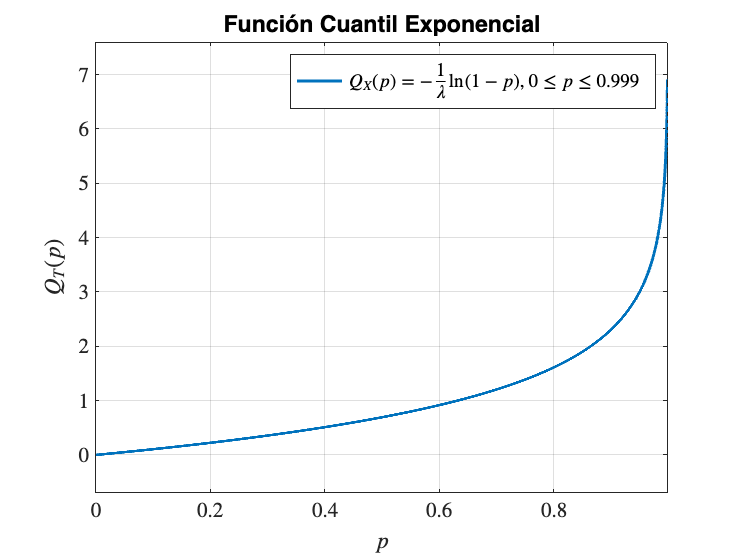

figure(7);
lambda = 1;
p = linspace(0,0.999,10000);
Q = -log(1-p)/lambda; % En MATLAB, log = logaritmo natural y log10 es logaritmo en base 10
superplot(p,Q,'Función Cuantil Exponencial',...
    '$p$','$Q_T(p)$');
legend('$Q_X(p)=-\frac{1}{\lambda}\ln(1-p),\, 0\leq p\leq 0.999$',...
    'interpreter','latex');

## Observaciones

La función cuantil puede emplearse para:

- Describir una variable aleatoria.

- Generar números aleatorios. Si $p\sim \mathcal{U}(0,1)$, entonces $Q_X(p)$ presenta la misma distribución de la variable aleatoria $X$.

- Revisar si una muestra aleatoria presenta una distribución particular, por ejemplo con la *qqplot*.

# Método de la Inversa

El método de la inversa se puede resumir en los siguientes dos pasos: 

- Generar un número aleatorio uniformemente distribuido con parámetros $a=0$ y $b=1$.

- Emplear el número obtenido en 1, como parámetro de entrada de la función cuantil.

## Generación de datos exponencialmente distribuidos

Para ilustrar el método de la inversa, se utilizará la función `randomexponencial` que se encuentra al final de este *Live script*. A continuación se comparan gráficamente las pdf de una muestra aleatoria generada por  `randomexponencial` y la de una exponencial.

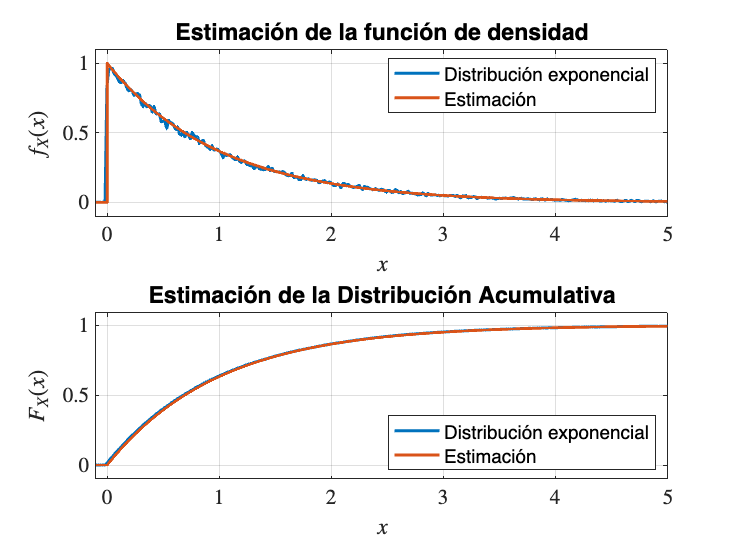

figure(8);
lambda = 1;
muestra = randomexponencial(lambda,1,100000);
pdfcdfcontinua(muestra,-0.1,5);
subplot(2,1,1)
hold on;
t = linspace(-0.1,5,10000);
pdf = exppdf(t,1/lambda);
superplot(t,pdf);
hold off;
legend('Distribución exponencial','Estimación');
subplot(2,1,2)
hold on;
t = linspace(-0.1,5,10000);
cdf = expcdf(t,1/lambda);
superplot(t,cdf);
hold off;
legend('Distribución exponencial','Estimación',...
    'Location','southeast');

# Q-Q plot

Es la gráfica de los cuantiles de una muestra aleatoria contra los cuantiles de una referencia (cuando no se indica, la referencia es normal estándar).

## Datos normalmente distribuidos

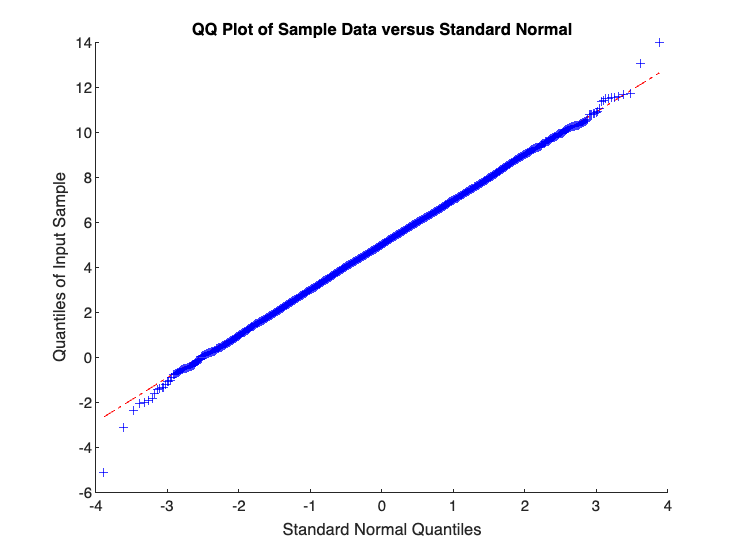

figure(9);
mu = 5;
sigma = 2;
muestra = mu +sigma*randn(1,10000);
qqplot(muestra);

## Datos exponencialmente distribuidos

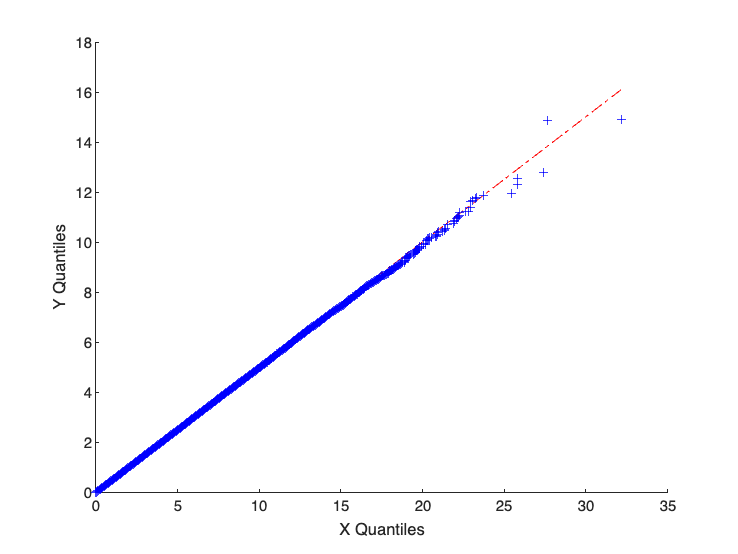

figure(10);
lambda = 0.5;
referencia = exprnd(1,1,1000000);
muestra = randomexponencial(lambda,1,1000000);
qqplot(muestra,referencia);

# Solución de la Tarea 14

## Código base

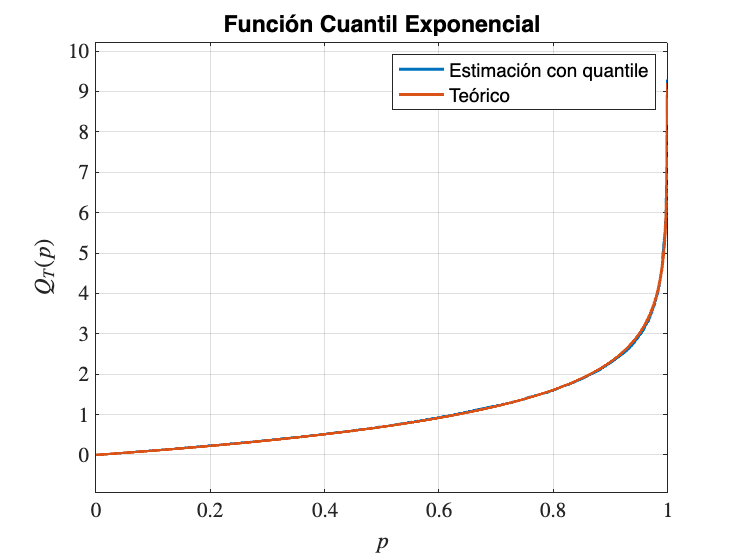

figure(11);
lambda = 1;
p = linspace(0,1,10000);
muestra = exprnd(1/lambda,1,10000);
Q = quantile(muestra,p);
superplot(p,Q,'Función Cuantil Exponencial',...
    '$p$','$Q_T(p)$');
teorica = -log(1-p)/lambda;
hold on;
superplot(p,teorica);
hold off;
legend('Estimación con quantile','Teórico');

## Función propuesta

type superfuncion.m

function [] = superfuncion(datos,nombre)
switch nargin
    case 0
        disp('Falta el vector de datos');
        return;
    case 1
        nombre = 'aleatorio';
end

p = linspace(0,1,100000);
datos = 1.0000000001*datos(:)'; % Materia de Investigación
numero = quantile(datos,p);

encabezado = ['function y = ',nombre,'(m,n)'];
cuerpo = 'numero = [';
final = '];if m==1, y = transpose(numero(randi(numel(numero),m,n))); else, y = numero(randi(numel(numero),m,n));end;end';


fid = fopen([nombre,'.m'],'w');

%fprintf(fid,'%s\n%s\n%10.8f\n%s\n',encabezado,cuerpo,numero,final);
fprintf(fid,'%s\n%s\n%s\n%s\n',encabezado,cuerpo,numero,final);
fclose(fid);
disp([nombre,'.m codificado. Revisa tu carpeta de MATLAB, por favor.']);
disp(['Luego puedes ejecutar: ',nombre,'(m,n).']);
end


## Prueba de `superfuncion`

Función que genera datos aleatorios exponencialmente distribuidos:

muestra = exprnd(1,1,1000000);
superfuncion(muestra,'exponencialrnd');

exponencialrnd.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: exponencialrnd(m,n).


Prueba de la función codificada:

exponencialrnd(4,5)

ans =     2.9934    1.1778    0.4700    0.1450    1.4483
    0.6627    0.3702    1.0605    1.0339    0.1671
    0.0160    1.6209    0.9725    0.0906    1.7180
    2.3228    0.8286    0.4595    0.0806    1.7836


QQplot de la función codificada:

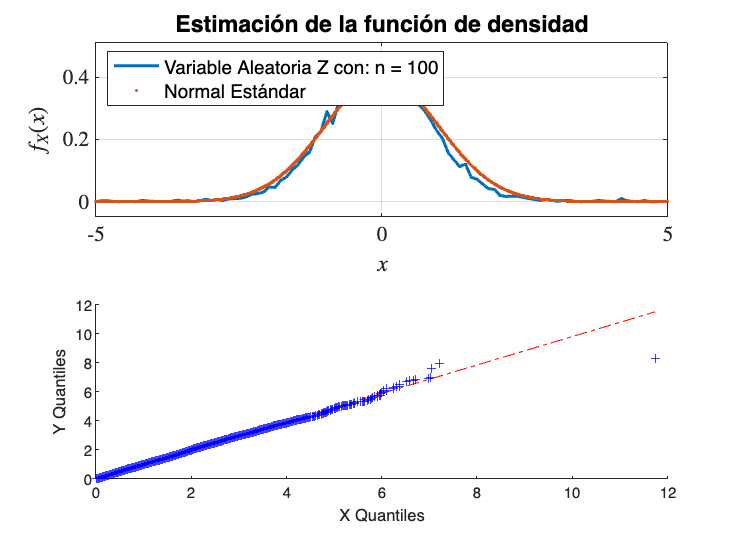

muestra = exponencialrnd(1,10000);
referencia = exprnd(1,1,10000);
qqplot(muestra,referencia);

# Actividad 4 del trabajo grupal

## Distribución de la muestra:

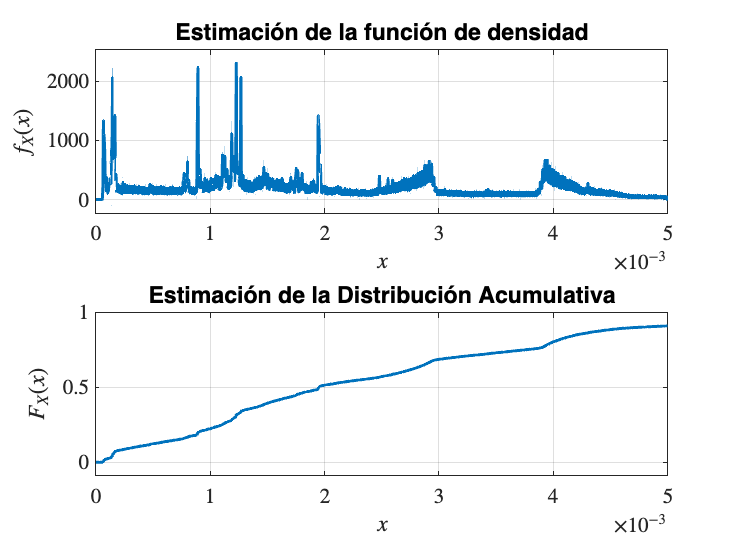

datos = load('BCpAug89.TL');
muestra = diff(datos(:,1)'); % Vector tea
figure(12);
pdfcdfcontinua(muestra,0,0.005);

## Codificación de la función

superfuncion(muestra,'agostornd');

agostornd.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: agostornd(m,n).


## Distribución de la función codificada

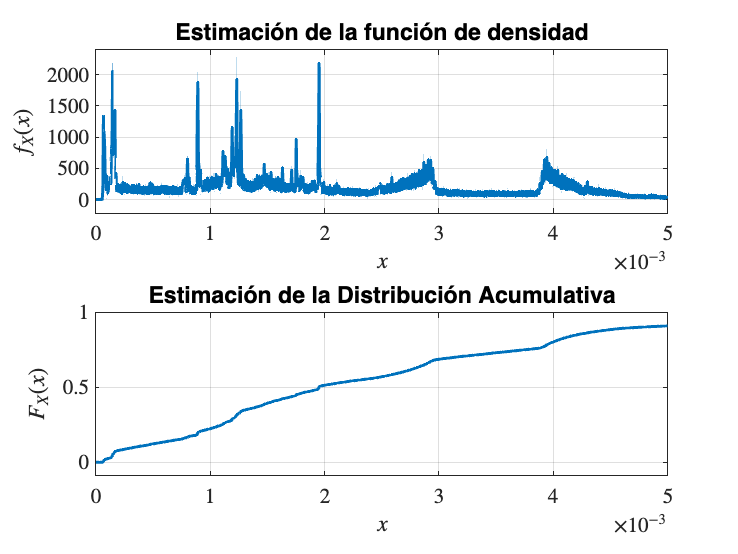

figure(13);
muestraagosto = agostornd(1,1000000);
pdfcdfcontinua(muestraagosto,0,0.005);

## QQplot de la función codificada

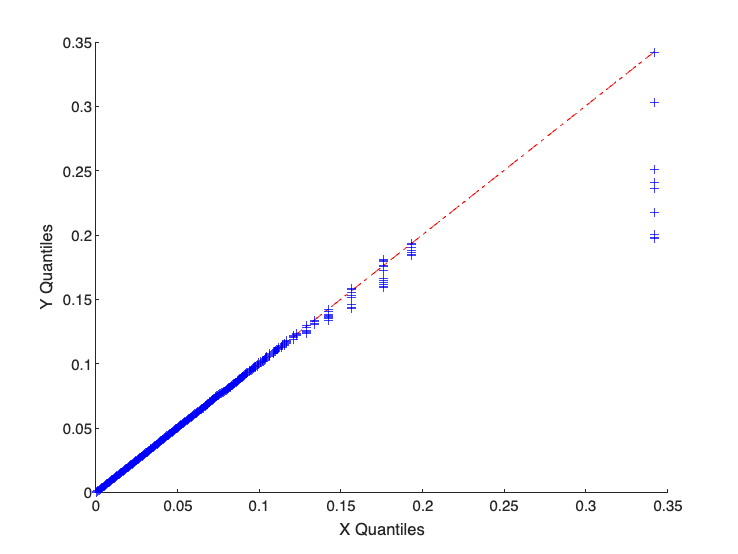

figure(14);
muestraagosto = agostornd(1,1000000);
qqplot(muestraagosto,muestra);

# Actividad 5 del trabajo grupal

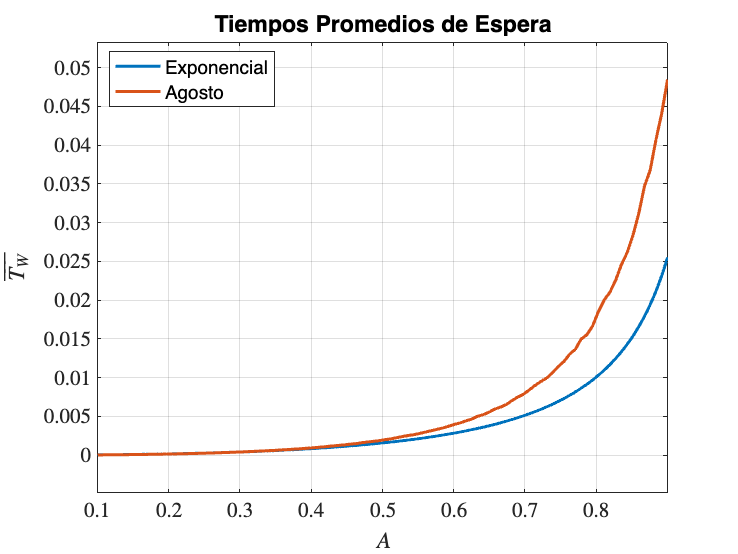

datos = agostornd(1,1000000);
lambda = 1/mean(datos);
Amin = 0.1;
Amax = 0.9;
simulaciones = 100;
A = linspace(Amin,Amax,simulaciones);
mu = lambda./A;
usuarios = 1000000;
tiempomedio = zeros(1,numel(mu));
for n = 1:numel(mu)
    tea = agostornd(1,usuarios);
    % tds = exprnd(1/mu,1,usuarios);
    tiempomedio(n) = xm1(mu(n),tea); % La función de la cola
end
A = linspace(Amin,Amax,1000);
mu = lambda./A;
teorico = 1./(mu-lambda)-1./mu; % Valor teórico obtenido para la cola
figure(15);
superplot(A,teorico,...
    'Tiempos Promedios de Espera','$A$',...
    '$\overline{T_W}$');
hold on;

A = linspace(Amin,Amax,simulaciones);
superplot(A,tiempomedio);
hold off;

legend({'Exponencial','Agosto'},...
    'location','best');
xlim([Amin Amax]);

# Entrega del tercer trabajo grupal

Sesión 15: sábado 25 de mayo de 2024.

# Funciones

Función que utiliza el método de la inversa para generar muestras aleatorias exponencialmente distribuídas con parámetro `lambda`.

function y = randomexponencial(lambda,m,n)
    y = -log(1-rand(m,n))/lambda;
end

Funciones que verifican el teorema del límite central, para muestras aleatorias con diferentes distribuciones:

function [] = limitecentralnormal(mu,sigma,n)
    repeticiones = 100000; %Número de veces que se repite el experimento
    minimo = -5;
    maximo = 5;
            
    datos = mu + sigma*randn(n,repeticiones);
    if n == 1
        Z = (datos'-mu)/(sigma/sqrt(n));
    else
        Z = (mean(datos)- mu)/(sigma/sqrt(n));
    end
    
    pdfcdfcontinua(Z,minimo,maximo);

    subplot(2,1,1);
    hold on;
    x = linspace(-5,5,10000);
    y = normpdf(x,0,1);
    plot(x,y,'.');
    hold off;    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
    
    subplot(2,1,2);
    hold on;    
    x = linspace(-5,5,10000);
    y = normcdf(x,0,1);
    plot(x,y,'.');
    hold off;    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
end

function [] = limitecentraluniforme(a,b,n)
    repeticiones = 100000; %Número de veces que se repite el experimento
    minimo = -5;
    maximo = 5;

    mu = (a+b)/2;
    sigma = (b-a)/sqrt(12);
    
    datos = unifrnd(a,b,n,repeticiones);
    if n == 1
        Z = (datos'-mu)/(sigma/sqrt(n));
    else
        Z = (mean(datos)- mu)/(sigma/sqrt(n));
    end
        
    pdfcdfcontinua(Z,minimo,maximo);

    subplot(2,1,1);
    hold on; 
    x = linspace(-5,5,10000);
    y = normpdf(x,0,1);
    plot(x,y,'.');
    hold off;    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
    
    subplot(2,1,2);
    hold on;    
    x = linspace(-5,5,10000);
    y = normcdf(x,0,1);
    plot(x,y,'.');
    hold off;    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
end

function [] = limitecentralexponencial(lambda,n)
    repeticiones = 100000; %Número de veces que se repite el experimento
    minimo = -5;
    maximo = 5;

    mu = 1/lambda;
    sigma = 1/lambda;
    
    datos = exprnd(1/lambda,n,repeticiones);
    if n == 1
        Z = (datos'-mu)/(sigma/sqrt(n));
    else
        Z = (mean(datos)- mu)/(sigma/sqrt(n));
    end
    
    pdfcdfcontinua(Z,minimo,maximo);

    subplot(2,1,1);
    hold on;    
    x = linspace(-5,5,10000);
    y = normpdf(x,0,1);
    plot(x,y,'.');
    hold off;
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
        
    subplot(2,1,2);
    hold on;    
    x = linspace(-5,5,10000);
    y = normcdf(x,0,1);
    plot(x,y,'.');
    hold off;    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
end

function [] = limitecentraldiscreta(x,p,n)
    repeticiones = 10000; %Número de veces que se repite el experimento
    minimo = -5;
    maximo = 5;

    mu = x*p';
    sigma = sqrt(((x.^2)*p')-mu^2);
    
    datos = va(x,p,n,repeticiones);
    if n == 1
        Z = (datos'-mu)/(sigma/sqrt(n));
    else
        Z = (mean(datos)- mu)/(sigma/sqrt(n));
    end
    
    pdfcdfcontinua(Z,minimo,maximo);

    subplot(2,1,1);
    hold on;    
    x = linspace(-5,5,10000);
    y = normpdf(x,0,1);
    plot(x,y,'.');
    hold off;    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
    
    subplot(2,1,2);
    hold on;    
    x = linspace(-5,5,10000);
    y = normcdf(x,0,1);
    plot(x,y,'.');
    hold off;
    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
end

function [] = limitecentralacel(n)
    repeticiones = 10000; %Número de veces que se repite el experimento
    minimo = -5;
    maximo = 5;
    
    load('datosacelerometro.mat');
    mu = mean(aceleracionz);
    sigma = std(aceleracionz);
    
    datos = acelrnd(n,repeticiones);
    if n == 1
        Z = (datos'-mu)/(sigma/sqrt(n));
    else
        Z = (mean(datos)- mu)/(sigma/sqrt(n));
    end
    
    pdfcdfcontinua(Z,minimo,maximo);

    subplot(2,1,1);
    hold on;    
    x = linspace(-5,5,10000);
    y = normpdf(x,0,1);
    plot(x,y,'.');
    hold off;    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
    
    subplot(2,1,2);
    hold on;    
    x = linspace(-5,5,10000);
    y = normcdf(x,0,1);
    plot(x,y,'.');
    hold off;
    
    legend(['Variable Aleatoria Z con: n = ',num2str(n)],...
        'Normal Estándar','Location','northwest');
end